# 基本的な確率分布の描画と性質

使用 toolbox

    Statistics and Machine Learning Toolbox 

ここでは、makedist を用いて統一した表記を紹介する。

## 1.  一様分布

### 分布オブジェクトの生成

例として、下限 $-3$、上限 $+5$ の連続一様分布オブジェクトを作成する。

pd1 = makedist("Uniform", lower=-4, upper=5);

### 分布の描画

$-10$から $+10$ の範囲で確率密度関数と累積分布を描く

x = -10:0.01:10;
plot(x, pdf(pd1, x))
hold on
    pd1_m = mean(pd1)

pd1_m = 0.5000

    pd1_s = std(pd1)

pd1_s = 2.5981

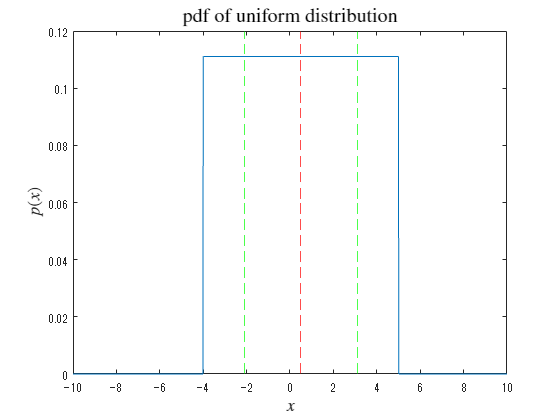

    xline(pd1_m, 'r--')
    xline(pd1_m + pd1_s, 'g--')
    xline(pd1_m - pd1_s, 'g--')
hold off
title('pdf of uniform distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$p(x)$", Interpreter="latex", FontSize=13)

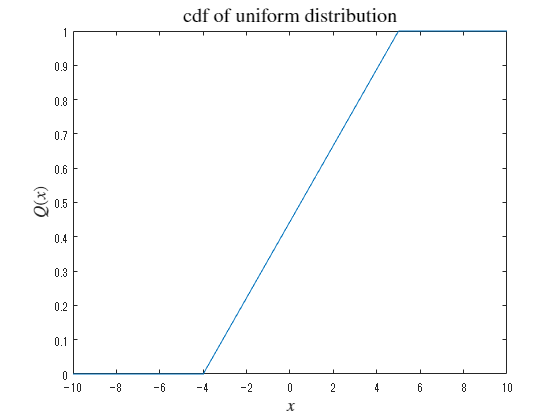


plot(x, cdf(pd1, x))
title('cdf of uniform distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$Q(x)$", Interpreter="latex", FontSize=13)

### 乱数の生成

乱数を生成し、ヒストグラムを描画する

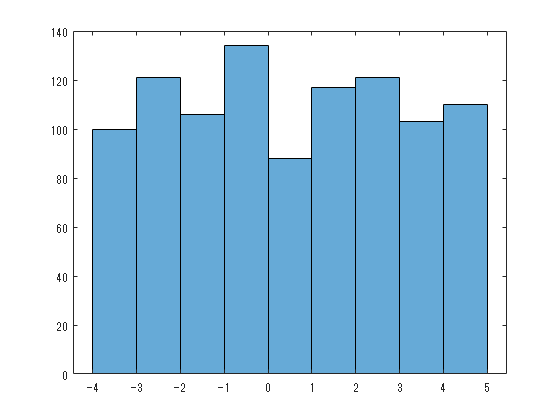

histogram(random(pd1,[1 1000]))

## 2．指数分布

### 分布オブジェクトの生成

例として、平均 1.7 の指数分布オブジェクトを作成する。

pd2 = makedist("Exponential", mu=1.7);

### 分布の描画

$0$から $+10$ の範囲で確率密度関数と累積分布を描く

x = 0:0.01:10;
plot(x, pdf(pd2, x))
hold on
    pd2_m = mean(pd2)

pd2_m = 1.7000

    pd2_s = std(pd2)

pd2_s = 1.7000

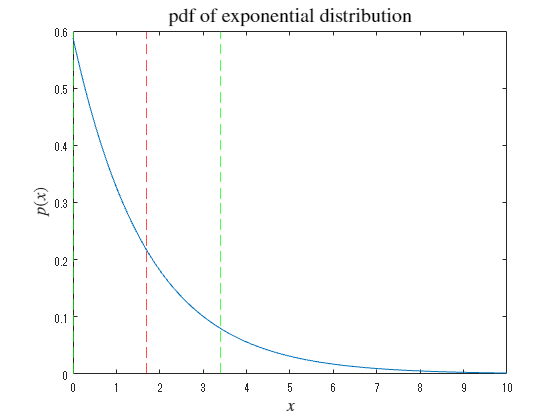

    xline(pd2_m, 'r--')
    xline(pd2_m + pd2_s, 'g--')
    xline(pd2_m - pd2_s, 'g--')
hold off
title('pdf of exponential distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$p(x)$", Interpreter="latex", FontSize=13)

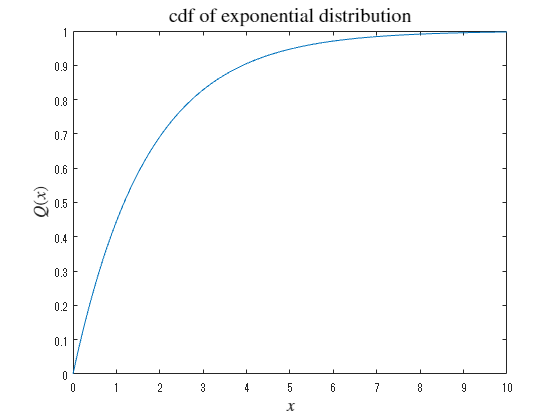


plot(x, cdf(pd2, x))
title('cdf of exponential distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$Q(x)$", Interpreter="latex", FontSize=13)

### 乱数の生成

乱数を生成し、ヒストグラムを描画する

rd2 = random(pd2,[1 1000])

rd2 =     0.2437    0.2620    3.8315    0.3468    0.7781    1.4436    1.0693    1.1215    0.9996    0.7206    0.2261    0.6882    2.5052    3.2356    1.4807    1.3627    0.3102    1.9166    1.1876    4.6345    1.6380    3.6151    1.0388    3.2250    0.7689    0.2457    1.4113    0.5708    1.8623    3.9440    0.1623    0.4053    0.0337    8.1615    2.1137    0.4172    0.1025    0.1833    3.6291    2.3150    0.2221    0.8732    2.7934    0.2664    2.4054    0.6343    1.1252    0.1999    0.1484    0.6290


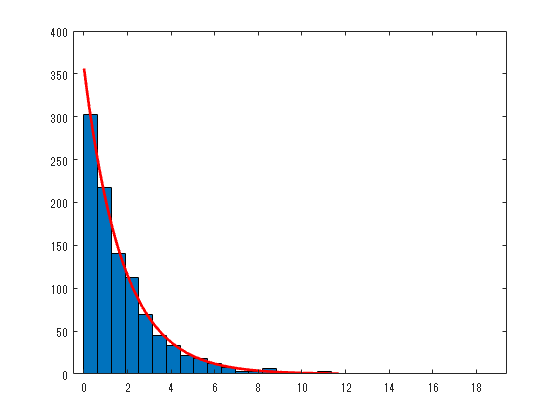

histfit(rd2, 30,"exponential")

fitdist(rd2',"exponential")

ans =   ExponentialDistribution

  指数 分布
    mu = 1.76639   [1.66182, 1.88119]


## 3．二項分布

### 分布オブジェクトの生成

例として、 $N=100$、 $p=0.35$ の二項分布オブジェクトを作成する。

pd3 = makedist("Binomial", "N",100, "p",0.35);

### 分布の描画

$0$から $+10$ の範囲で確率密度関数と累積分布を描く

x = 0:1:100;
plot(x, pdf(pd3, x), 'o-')
hold on
    pd3_m = mean(pd3)

pd3_m = 35

    pd3_s = std(pd3)

pd3_s = 4.7697

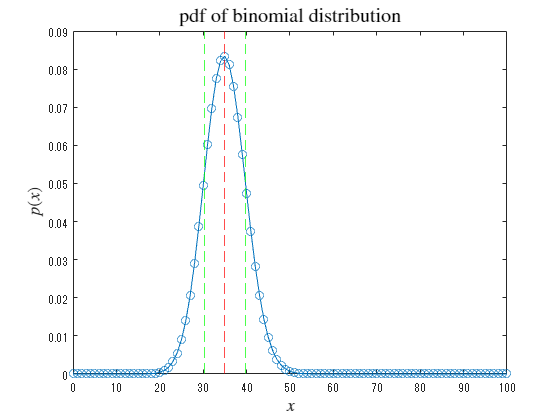

    xline(pd3_m, 'r--')
    xline(pd3_m + pd3_s, 'g--')
    xline(pd3_m - pd3_s, 'g--')
hold off
title('pdf of binomial distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$p(x)$", Interpreter="latex", FontSize=13)

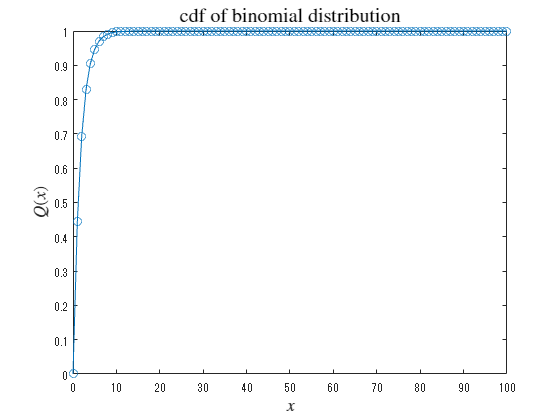


plot(x, cdf(pd2, x), 'o-')
title('cdf of binomial distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$Q(x)$", Interpreter="latex", FontSize=13)

### 乱数の生成

乱数を生成し、ヒストグラムを描画する

rd3 = random(pd3,[1 1000])

rd3 =     36    37    40    27    33    41    34    41    34    32    42    33    33    36    38    33    36    35    37    37    31    41    35    36    47    29    36    31    31    34    41    34    32    42    39    31    39    38    35    39    35    30    28    38    29    39    29    31    30    34


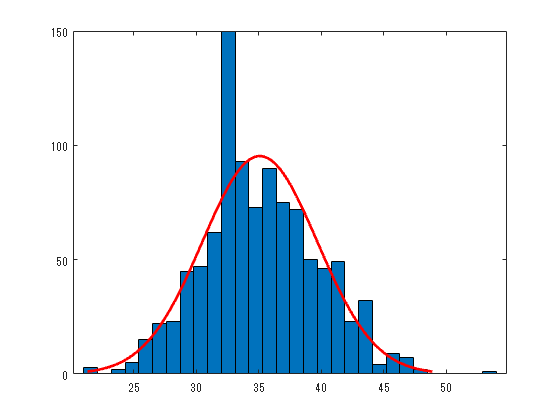

histfit(rd3, 30,"normal")

fitdist(rd3',"normal")

ans =   NormalDistribution

  正規 分布
       mu =  35.086   [34.8003, 35.3717]
    sigma = 4.60389   [4.41058, 4.81505]


## 4．正規分布（ガウス分布）

### 分布オブジェクトの生成

例として、 $\mu=5$、 $\sigma=2.1$ の二項分布オブジェクトを作成する。

pd4 = makedist("normal","mu",5,"sigma",2.1);

### 分布の描画

$0$から $+10$ の範囲で確率密度関数と累積分布を描く

x = -5:0.01:15;
plot(x, pdf(pd4, x), '-')
hold on
    pd4_m = mean(pd4)

pd4_m = 5

    pd4_s = std(pd4)

pd4_s = 2.1000

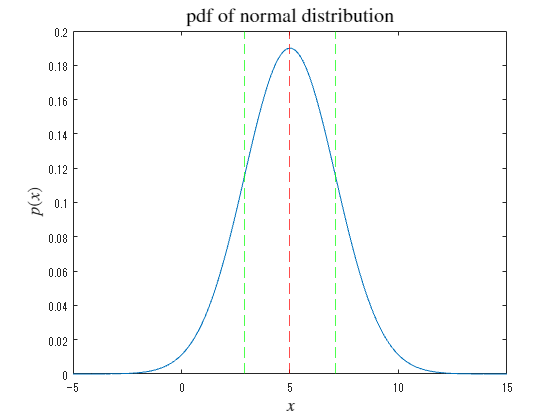

    xline(pd4_m, 'r--')
    xline(pd4_m + pd4_s, 'g--')
    xline(pd4_m - pd4_s, 'g--')
hold off
title('pdf of normal distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$p(x)$", Interpreter="latex", FontSize=13)

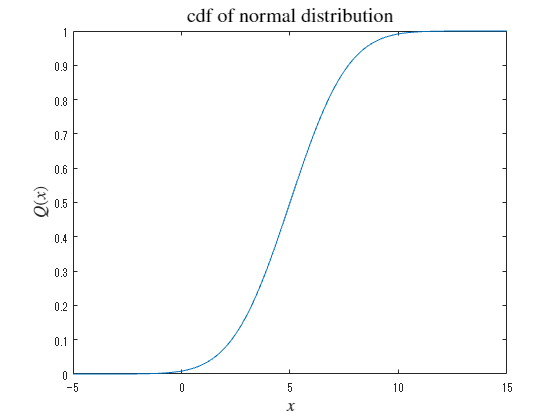


plot(x, cdf(pd4, x), '-')
title('cdf of normal distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$Q(x)$", Interpreter="latex", FontSize=13)

### 乱数の生成

乱数を生成し、ヒストグラムを描画する

rd4 = random(pd4,[1 1000])

rd4 =     9.7441    5.2541    1.2820    5.8811    5.8873    5.5369    8.1014    3.4104    6.1540    7.0385    2.4053    2.4342    3.7522    4.4694    3.5528    5.0926    1.8941    5.7379    7.8158    4.5254    4.0065    5.4638    4.9128    8.3422    3.4555    4.9765    7.0332    1.5198    6.7035    5.0024    5.0738    6.5498    3.7303    4.5947    4.4214    5.0428    5.4128    3.1554    2.3847    7.5476    4.1723    8.5252    1.3190    4.1811    6.5152    5.2886   -1.1761    3.1481    3.8328    4.4720


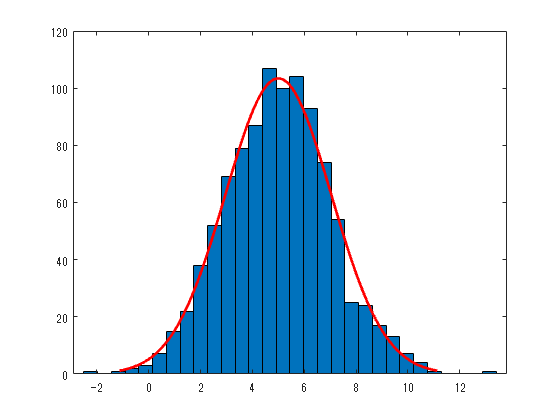

histfit(rd4, 30,"normal")

fitdist(rd4',"normal")

ans =   NormalDistribution

  正規 分布
       mu = 4.99992   [4.87308, 5.12676]
    sigma = 2.04407   [1.95824, 2.13782]


## 参考文献

- [https://jp.mathworks.com/help/stats/index.html?s_tid=CRUX_lftnav](https://jp.mathworks.com/help/stats/index.html?s_tid=CRUX_lftnav)

- [https://jp.mathworks.com/help/stats/histfit.html](https://jp.mathworks.com/help/stats/histfit.html)

- [https://jp.mathworks.com/help/stats/fitdist.html](https://jp.mathworks.com/help/stats/fitdist.html)